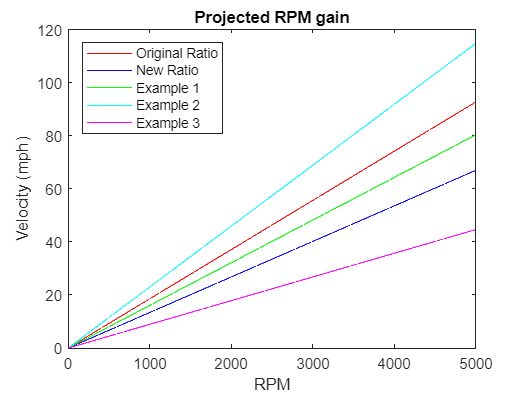

d = 27; %% in inches

currfrontSproket = 12; %% number of teeth in the front sproket
currbackSproket = 52; %% number of teeth in the rear sproket
currentGearRatio = currbackSproket/currfrontSproket; %% current gear ratio

newfrontSproket = 12;  %% number of teeth in the front sproket
newbackSproket = 72; %% number of teeth in the rear sproket
newGearRatio = newbackSproket/newfrontSproket; %% new gear ratio

RPMscale = (1:5000);
newSpeed = (RPMscale ./ newGearRatio) .* (d * pi * 60/63360);
originalSpeed = (RPMscale ./ currentGearRatio) .* (d * pi * 60 /63360);
example1speed = (RPMscale ./ 5) .* (d * pi * 60 /63360);
example2speed = (RPMscale ./ 3.5) .* (d * pi * 60/63360);
example3speed = (RPMscale ./ 9) .* (d * pi * 60/63360);

figure
plot(RPMscale, originalSpeed, 'r', RPMscale, newSpeed, 'b', RPMscale, example1speed, 'g', RPMscale, example2speed, 'c', RPMscale, example3speed, "magenta")
xlabel('RPM')
ylabel('Velocity (mph)')
title('Projected RPM gain')
legend(["Original Ratio","New Ratio","Example 1", "Example 2", "Example 3"])
legend("Position",[0.15791,0.66033,0.26541,0.23169])